**What do the following have in common?...**

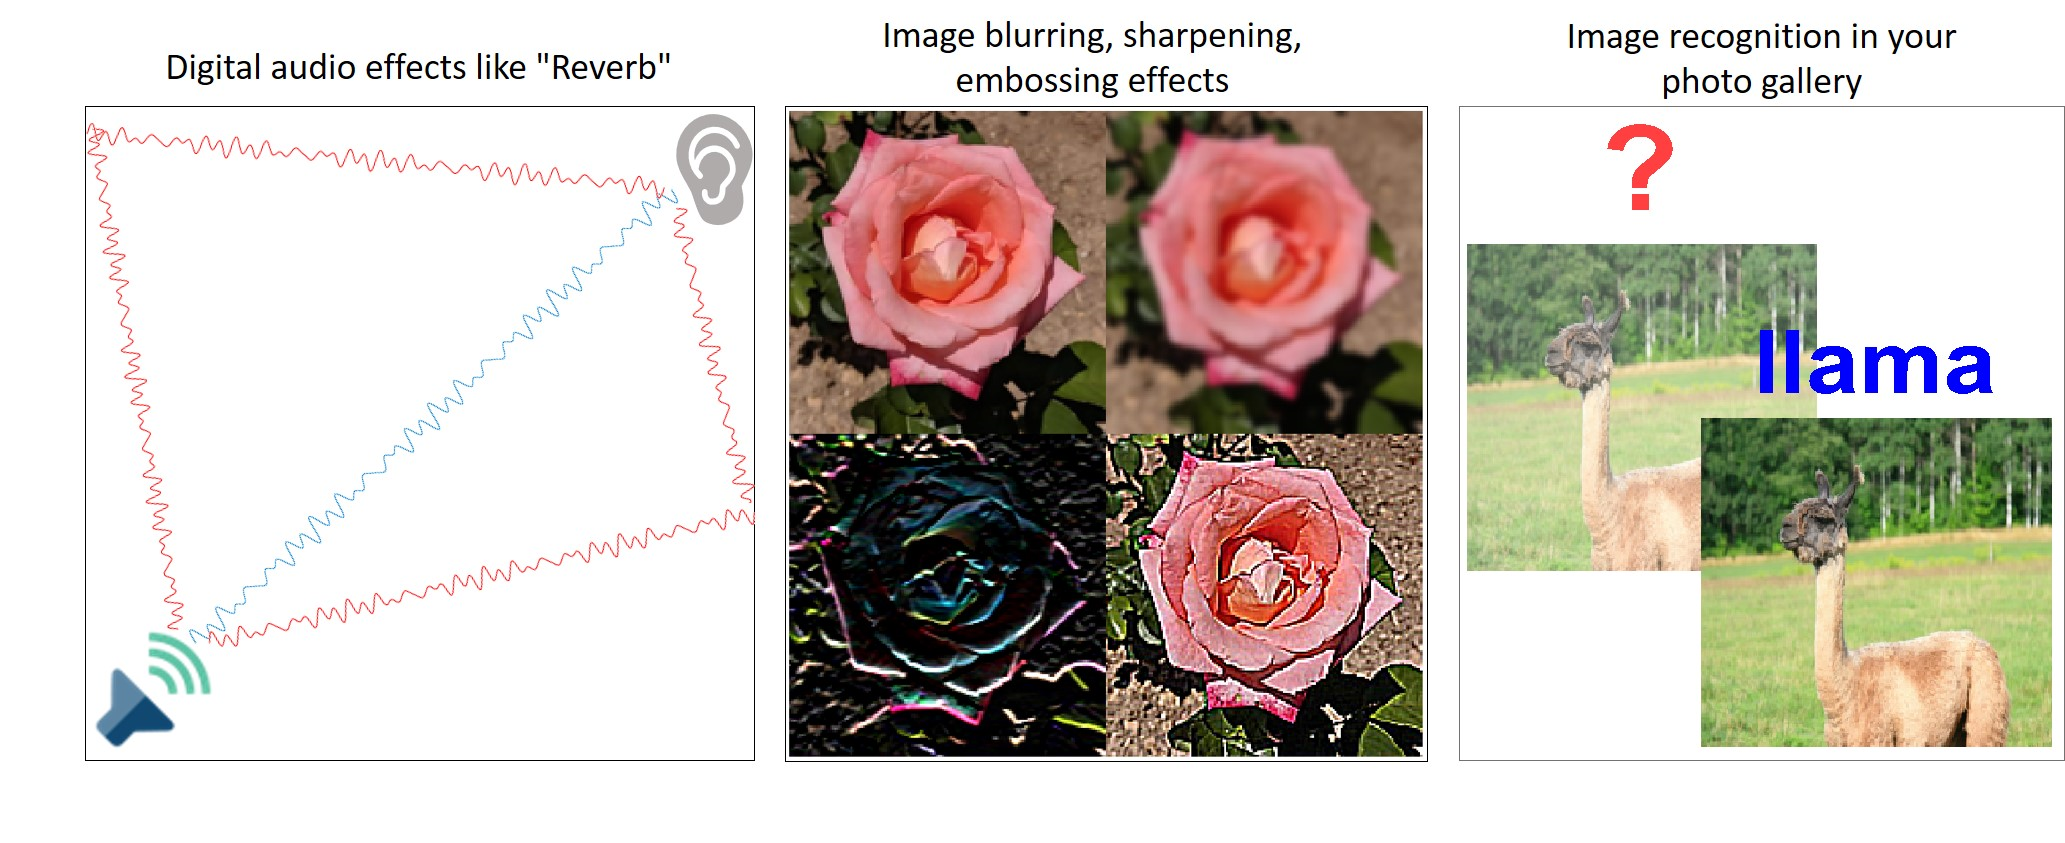

**... it's Convolution! **

# Convolution: Basics

## What is convolution?

The convolution of two continuous signals is another continuous signal. The value at some time `t `is defined as the integral of the products of the two input signals, where one of the signals has been shifted in time by `t` and flipped.

                                    
$$w\left(t\right)=\int_{-\infty }^{\infty } u\left(\tau \right)v\left(t-\tau \right)d\tau$$
  

Let's visualize this process with two simple pulse signals.

% Set up the time step and time (X) axis data.
ts = 1/1000;             % Time step
t = -3:ts:3;             % Time vector

Visit the documentation to learn more about the inputs to these functions: [rectpuls](https://www.mathworks.com/help/signal/ref/rectpuls.html), [tripuls](https://www.mathworks.com/help/signal/ref/tripuls.html)

***Task: ****Use the sliders and dropdowns to set different parameters for the signals. Click ****Run**** to view the convolution process and its result. *

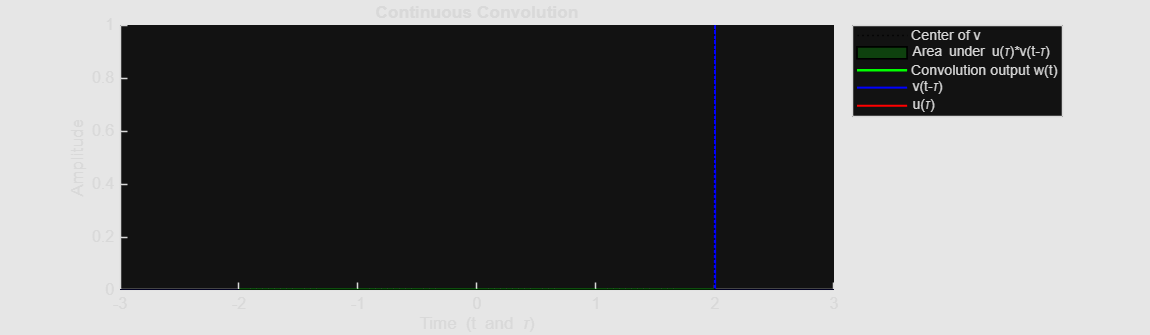

u  = tripuls(t,2) *0 ; % The first slider sets the width, the second slider scales the amplitude
v  = rectpuls(t,0) *1 ; % The first slider sets the width, the second slider scales the amplitude
 

animateConvolution(u,v,ts,t,-2);

This process is also called **linear convolution.**

***Try***

- *Change *`u`* to a rectangular pulse of width 1.5 and amplitude 1. *

- *Change *`v`* to a triangular pulse of width 1.5 and amplitude 1.*

- *Swap the *`u`* and *`v`* signal settings*`.`

- *Set *`u`* and *`v`* both to triangular pulse with different widths and amplitudes.*

- *Use the third input to set the skewness when using the triangular pulse signals.*

***Reflect***

## ***Does the order of inputs matter? Is convolution commutative?***

No, the order of the inputs **does not affect the final result**.

Convolution **is commutative**, meaning:

u(t)∗v(t)=v(t)∗u(t)

u(t) * v(t) = v(t) * u(t)

u(t)∗v(t)=v(t)∗u(t)

and in discrete time:

u[n]∗v[n]=v[n]∗u[n]

u[n] * v[n] = v[n] * u[n]

u[n]∗v[n]=v[n]∗u[n]

What we observe in the demo:

When you swap u and v, the animation process looks different(because a different signal is being flipped and shifted), but the final output waveform www remains exactly the same.

## ***Describe your general observations about the convolution output ***`w`*** compared to the inputs ***`u`*** and ***`v`***? ***

** 1. Shape**

The output is a **blend of both input signals**.

Rectangular * rectangular → triangular

Rectangular * triangular → smooth “rounded” trapezoid-like shape

Triangular * triangular → wider, smoother curve

**2. Width (Duration)**

The output signal is **wider than both inputs**.

For continuous pulses: Width of w= Width of u + Width of v

So convolution **adds durations**.

**3. Amplitude**

The amplitude depends on the **overlap area** between the signals.

Maximum output occurs when the two signals **overlap the most** (centers aligned).

**4. Sliding & overlap interpretation**

Convolution can be understood as:

“Measure how much two signals overlap as one slides across the other.”

Small overlap → small output

Large overlap → large output

No overlap → output = 0

**5. Effect of scaling**

If you increase the amplitude of any input → output amplitude increases proportionally.

**6. Effect of skewness (triangular pulse parameter)**

Changing skewness:

shifts where the **peak of the output occurs**

changes symmetry of the result

**7. Length of discrete convolution output**

If both input sequences have length **L**: Length of w =  2 L − 1

If the lengths are **M and N**:

Length of w=M+N−1

## Compute convolution

The animation above illustrates continuous convolution, which is defined as an integral. This was achieved by approximating a continuous result based on a discrete summation. Discrete convolution is defined by this summation:

                                    
$$w\left(k\right)=\sum_n u\left(n\right)\cdot v\left(k-n\right)$$


You can use the [`conv`](https://www.mathworks.com/help/releases/R2020a/matlab/ref/conv.html) function to compute the discrete convolution of two input sequences or discrete signals.

Let us define two 1-D discrete signals and convolve them using the `conv` function. 

***Task: ****Use the sliders and dropdowns to set different parameters for the two input signals.*

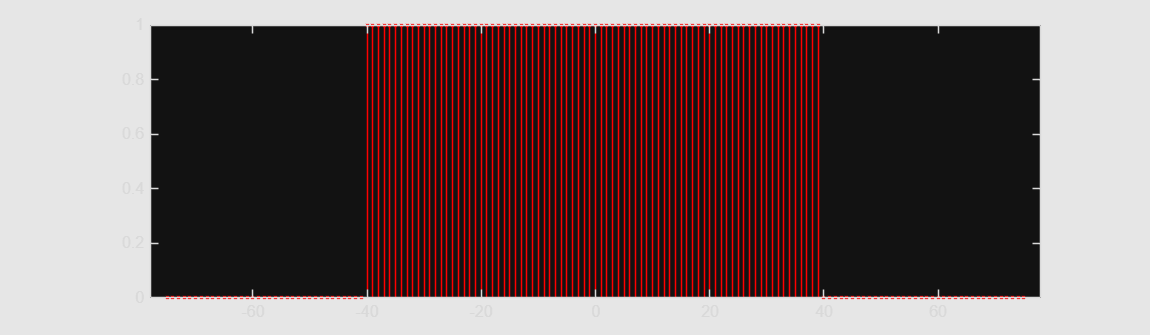

figure("Position",[0 0 1200 350], "Color", [0.9 0.9 0.9]);

L = 151;                   % length of input sequences u and v. Keep it odd for simplicity
n = -(L-1)/2:(L-1)/2;      % X axis data for the signals


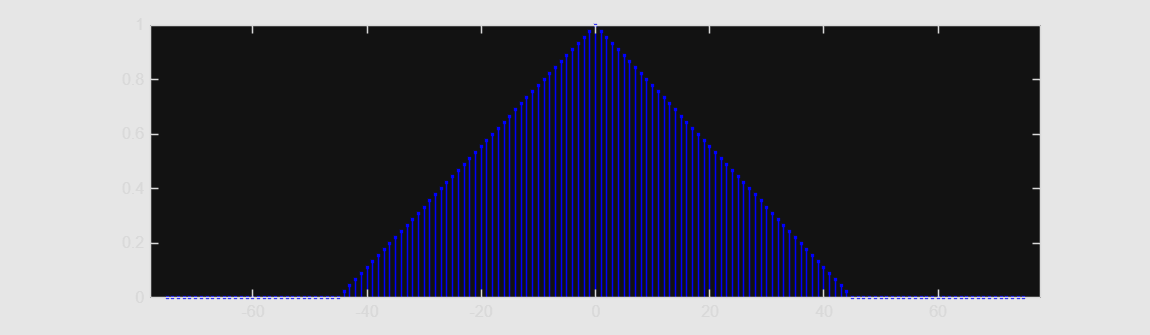

u  = rectpuls(n,80);
stem(n,u,"r.")

v  = tripuls(n,90);
stem(n,v,"b.")

Output length = 301


We use the `conv` function to convolve two vectors in MATLAB.

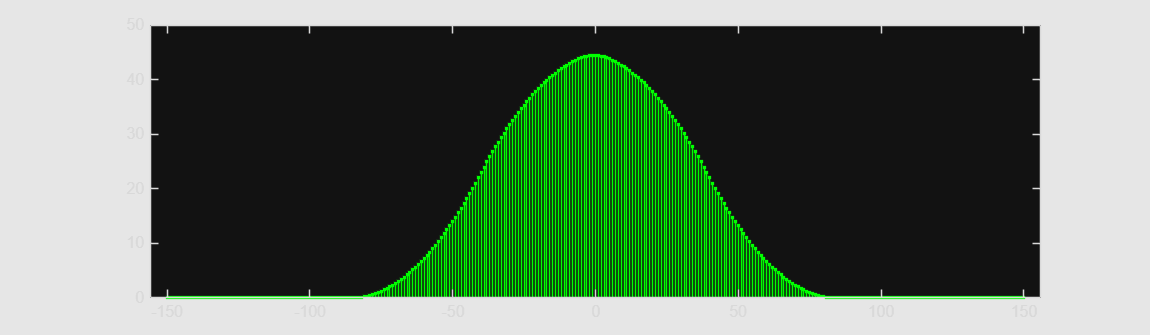

w  =  conv(u, v);
disp("Output length = " + length(w))

nOut = -(L-1):(L-1);
stem(nOut,w,"g.");

***Reflect***

## ***How is the length of convolution output related to the length ***`L`*** of the two input signals? ***

From the observations of the discrete-time convolution demo, when both input sequences have the same length LLL, the length of the output sequence is: 2L−1

This happens because during convolution one sequence slides across the other. The output starts when the two signals first overlap and ends when they completely move past each other. Therefore, the total number of samples in the result becomes the sum of the individual lengths minus one.

## ***What do you think will happen if the input sequences had different lengths? say, ***`M`*** and ***`N`***, instead of ***`L`***.***

If the two input sequences have different lengths, say MMM and NNN, then the length of the convolution output becomes: M+N−1

This is because the sliding operation now takes place over a longer interval. The convolution output includes all positions where the two sequences overlap even by a single sample.

## **Helper function**

Function for creating the convolution animation.

function animateConvolution(f,h,ts,t,t0)

fs = 1/ts;
Cind = find(t == t0);   % Index of starting point in t
h_center = t0;

% Shift signal to extreme and flip
h = circshift(h,find(t==0) - Cind);
h = fliplr(h);

% Initialize plots for animation
figure("Position",[0 0 1200 350],"Color", [0.9 0.9 0.9]);
title("Continuous Convolution")
xlabel("Time (t and \tau)")
ylabel("Amplitude")

hold on
p0 = plot(t,f,"r","LineWidth",1.2);
p1 = plot(t,h,"b","LineWidth",1.2);
p2 = plot(t0,sum(f.*h)/fs,"g-","LineWidth",1.5);
p3 = area(t,f.*h,"FaceColor","g","FaceAlpha", 0.2,"EdgeColor","k","LineWidth", 1,"ShowBaseLine","off");
p4 = xline(t0, ":k");
legend("u(\tau)","v(t-\tau)","Convolution output w(t)","Area under u(\tau)*v(t-\tau)","Center of v","Location","bestoutside")

xlim([t(1) t(end)]);

% Loop to update plots to visualize the process and result of convolution.
K = fs/20;  % steps to shift the signal in each iteration

while h_center <= abs(t0)
       
    % Convolve
    h = circshift(h,K);    % shift the second signal
    prod = f.*h;           % compute product of the signals
    y = sum(prod)/fs;      % compute integral of product i.e. area under the product    
    h_center = h_center + K/fs;
    
    % Update plots
    p1.YData = h;
    p2.XData = [p2.XData, h_center];
    p2.YData = [p2.YData, y];    
    p3.YData = prod;
    p4.Value = h_center;
    drawnow
    
   
end
hold off

end


## **TASK 3:**

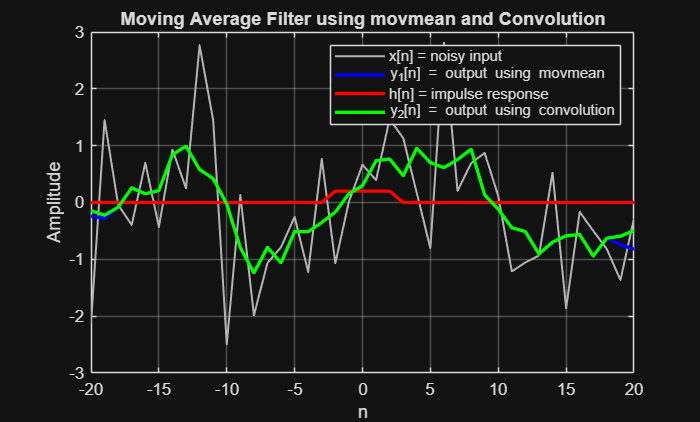

clc; 
clear; close all;

%% (a) Generate noisy signal and apply 5-point moving average 

n = -20:20; % given range

z = sin(0.3142*n); % original clean sinusoidal signal
noise = randn(size(n));           
x = z + noise;  % noisy signal

y1 = movmean(x, 5);  % 5-point moving average filter output


%%  (b) Find impulse response of the system 

delta = (n == 0);  % unit impulse at n=0

h = movmean(delta, 5);% impulse response of the moving average filter


%%  (c) Convolve x[n] with h[n] 

y2 = conv(x, h, 'same');% this keeps output length equal to input


%% (d)Plot all signals in one figure

figure;
plot(n, x,'Color',[0.7 0.7 0.7], 'LineWidth', 1.2); 
hold on;
plot(n, y1,'b','LineWidth', 2);
plot(n, h, 'r','LineWidth', 2);
plot(n, y2,'g','LineWidth', 2);
grid on;
xlabel('n');
ylabel('Amplitude');
title('Moving Average Filter using movmean and Convolution');
legend('x[n] = noisy input', ...
       'y_1[n] = output using movmean', ...

       'h[n] = impulse response', ...
       'y_2[n] = output using convolution');

## **TASK 4**

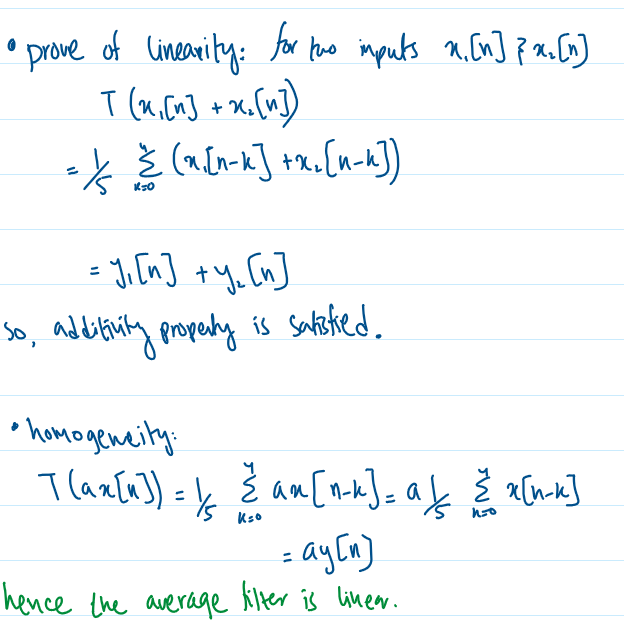

(task 5 done after task 6)

## **TASK 6**

clc; 
clear; 
close all;

%% ---------- Import impulse response ---------------
[h, Fh] = audioread('C:\Users\Administrator\OneDrive - Habib University\Sem 4\Signals & Systems\MatLab\Lab05_Resources\Lab05_Resources\1st_baptist_nashville_balcony.wav'); % impulse response of church
disp(size(h)); % checking channels

      288000           2



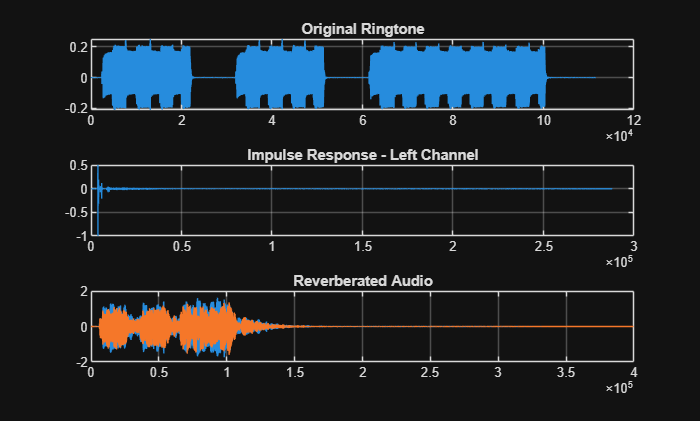


soundsc(h, Fh);                 % play the impulse response
pause(length(h)/Fh + 1);       

%% ------------ Import ringtone -------------
[x, Fx] = audioread('ringtone.wav');
soundsc(x, Fx);                    
pause(length(x)/Fx + 1);

%% ----------- Apply reverberation ------------
% For stereo impulse response: separate channels
h1 = h(:,1); 
h2 = h(:,2);

y1 = conv(x, h1);  % left channel convolution
y2 = conv(x, h2);  % right channel convolution

y = [y1, y2];      % combine to stereo

soundsc(y, Fx);    % play reverberated ringtone

%% ------------- Plot audio signals ------------
figure;
subplot(3,1,1); 
plot(x); 
title('Original Ringtone'); 
grid on;
subplot(3,1,2); 
plot(h1); 
title('Impulse Response - Left Channel'); 
grid on;
subplot(3,1,3); 
plot(y); 
title('Reverberated Audio'); 
grid on;

**APPLYING THIS EFFECT TO MY OWN SOUND FILE:**

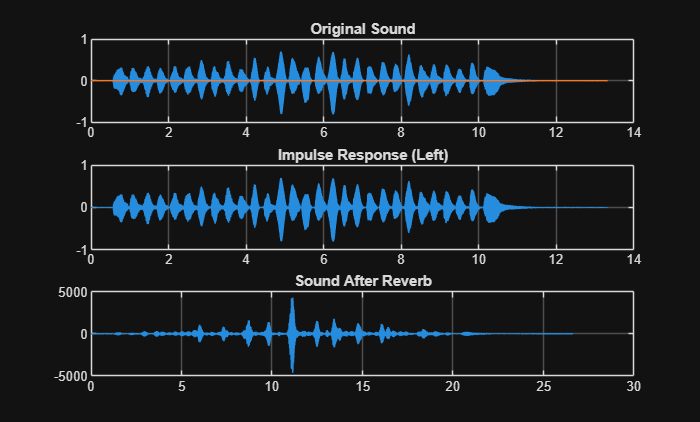

clc; clear; close all;

%%grab my own sound first
[soundData, Fs] = audioread('C:\Users\Administrator\OneDrive - Habib University\Sem 4\Signals & Systems\MatLab\Lab05_Resources\Lab05_Resources\modern-viola-c-major-bow-lift.wav');

%hearing how it sounds
soundsc(soundData, Fs)
pause(length(soundData)/Fs + 1)

%% Splitting channels in case it's stereo
if size(soundData,2) == 2
    leftChan  = soundData(:,1);  % left side
    rightChan = soundData(:,2);  % right side
else
    leftChan  = soundData;       % just copy for both
    rightChan = soundData;
end

%adding some echo/reverb
outLeft  = conv(leftChan, leftChan);   % left channel
outRight = conv(rightChan, rightChan); % right channel

% Put them together for stereo
finalSound = [outLeft, outRight];

% Limiting the amplitude
finalSound = finalSound / max(abs(finalSound(:)));

% Hearing the reverb version: NOTE It will take sometime to convolute
% because of lenght of audio.
soundsc(finalSound, Fs)
pause(length(outLeft)/Fs + 1)

tInput  = (0:length(soundData)-1)/Fs;
tImpulse = (0:length(leftChan)-1)/Fs;
tOutput = (0:length(outLeft)-1)/Fs;

figure;

subplot(3,1,1)
plot(tInput, soundData)
title('Original Sound')
grid on

subplot(3,1,2)
plot(tImpulse, leftChan)
title('Impulse Response (Left)')
grid on

subplot(3,1,3)
plot(tOutput, outLeft)
title('Sound After Reverb')
grid on

## **TASK 5: Generating sine wave**

% Now generation sine wave and using findpeaks to verify it:
clc;
clear;
close all;

%% ===================== Generate Input Sine Wave =====================
Fs = 1000;                 % Sampling frequency (Hz)
t  = 0:1/Fs:1;            

f0 = 5;                    % Input sine frequency (Hz)
x  = sin(2*pi*f0*t);    

%% ===================== Define Two LTI Systems ================
h1 = ones(1,5)/5;

% System 2 → Exponential decay system
n  = 0:15;
h2 = (0.8).^n;

%% ===================== Pass Through Systems ========================
y1 = conv(x, h1, 'same');
y2 = conv(x, h2, 'same');

%% ===================== Plot Input and Outputs ======================
figure('Visible','on'); % opens a visible figure window
plot(t, x, 'k', 'LineWidth', 1.5); hold on;
plot(t, y1, 'r', 'LineWidth', 1.2);
plot(t, y2, 'b', 'LineWidth', 1.2);
grid on;
legend('Input x(t)','Output y_1(t)','Output y_2(t)');
title('Sine Wave Through Two LTI Systems');
xlabel('Time (s)');
ylabel('Amplitude');
drawnow;  % forces the plot to render immediately

%% ===================== Frequency Verification ======================
% --- For System 1 ---
[pks1, locs1] = findpeaks(y1, t);
T1 = locs1(2) - locs1(1);
f1 = 1/T1;

% --- For System 2 ---
[pks2, locs2] = findpeaks(y2, t);
T2 = locs2(2) - locs2(1);
f2 = 1/T2;

%% ===================== Display Results =============================
disp("Input Frequency: " + f0)
disp("System 1:");
disp("Time Period T1: " + T1)
disp("Output Frequency f1: " + f1)

disp("System 2:");
disp("Time Period T2 (s): " + T2)
disp("Output Frequency f2 (Hz): " + f2)

output:

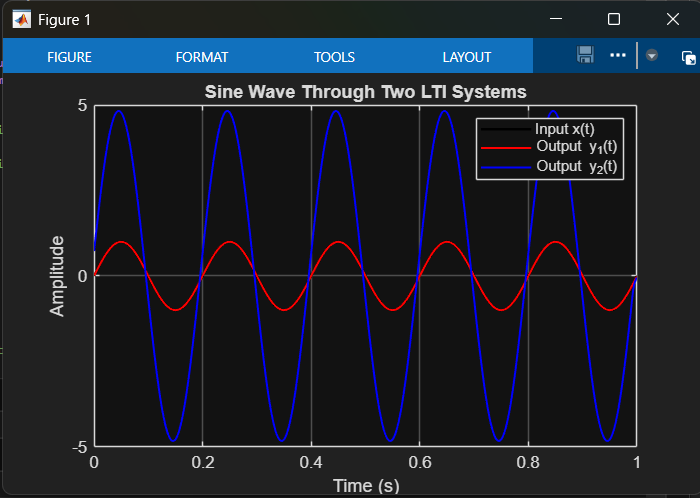

## **POST LAB: TASK 7:**

% MY OWN COSTOM FUNCTION:

function w = discrete_convo(u, v)

% without using MATLAB built-in conv()

Nu = length(u);
Nv = length(v);

% Output length
Nw = Nu + Nv - 1;

% Initialize output
w = zeros(1, Nw);

% Convolution sum
for n = 1:Nw
    for k = 1:Nu

        % Check overlap condition
        if (n - k + 1 > 0) && (n - k + 1 <= Nv)
            w(n) = w(n) + u(k) * v(n - k + 1);
        end

    end
end

end

%TEST of function:

clc
clear
close all

%% Given signals
x = [1 2 3 4 5];        % 0 ≤ n ≤ 4
h = [1 2 1];            % -1 ≤ n ≤ 1

nx = 0:4;
nh = -1:1;

%% Manual convolution
y_manual = discrete_convo(x, h);

%% Built-in convolution (for comparison only)
y_builtin = conv(x, h);

%% Output index
ny = (nx(1) + nh(1)) : (nx(end) + nh(end));

%% Display results
disp("Manual convolution result:")
disp(y_manual)


Manual convolution result:


disp("Built-in conv result:")

     1     4     8    12    16    14     5



disp(y_builtin)


Built-in conv result:


%% Plotting

     1     4     8    12    16    14     5



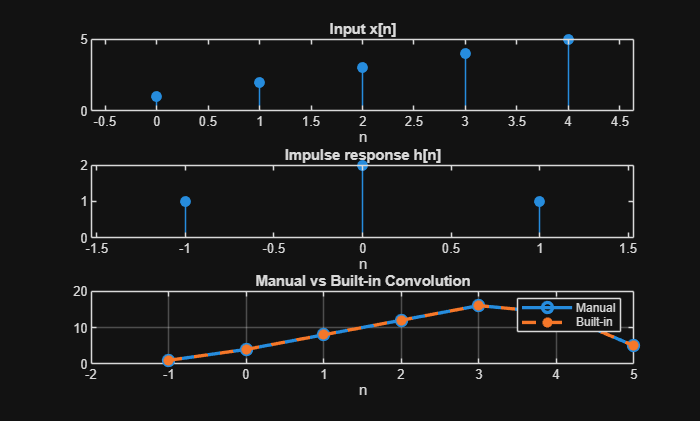

figure

subplot(3,1,1)
stem(nx, x, 'filled')
title('Input x[n]')
xlabel('n')

subplot(3,1,2)
stem(nh, h, 'filled')
title('Impulse response h[n]')
xlabel('n')

subplot(3,1,3)
plot(ny, y_manual, 'o-', 'LineWidth', 2)
hold on 
plot(ny, y_builtin, '*--', 'LineWidth', 2)
title('Manual vs Built-in Convolution')
xlabel('n')
legend('Manual','Built-in')

axis([-2 5 0 20])
grid on     % set axis as requested